## **1. Enviroment Setting**

    Clean up all the data in Workspace & information in Command Window.

clc;clear

## 2. Parameter Setting

    According to condition of design, first setting up all the parameter we needed.

source_radius = 5;
n_glass = 1.5;
n_air = 1;
TIR_angle_correct = 0;
R_angle_correct = 0;

## 3. Refraction Angle Calculation

###     3-1 Light Source to side incident surface

        Calculate each emission angle of the point source transmit to the side incident surface position coordinate.

emission_angle_side = 0:0.5:60;
s_i_s_p = zeros(2,numel(emission_angle_side)); % side_incident_surface_position
s_i_s_p(1,:) = source_radius;
s_i_s_p(2,:) = source_radius*tand(emission_angle_side);


###     3-2 Refraction angle calculation

        According to Snell's law, we can calculate refraction angle of each emission angle after penetrate the side incidient surface.

refraction_angle_top = asind(n_air*sind(emission_angle_side)/n_glass);

## 4. Total Internal Reflection Surface Desigin

### 4-1. TIR Surface Calculation

        So, we get the position on side incident surface and refraction angle. Next step, we are going to calculate TIR surface. 

TIR_s_p = zeros(2,numel(emission_angle_side));
surf_x = source_radius+1;

dx = surf_x-source_radius;
dy = dx*tand(refraction_angle_top(1));
surf_y = s_i_s_p(2,1)+dy;
TIR_s_p(1,1) = surf_x;
TIR_s_p(2,1) = surf_y;

for i = 1:numel(emission_angle_side)-1
    unit_vector = [cosd(45+TIR_angle_correct/2+refraction_angle_top(i)/2),sind(45+TIR_angle_correct/2+refraction_angle_top(i)/2)];
    a_0 = unit_vector(1);          a_1 = cosd(refraction_angle_top(i+1));
    x_0 = surf_x;                  x_1 = s_i_s_p(1,i+1);
    b_0 = unit_vector(2);          b_1 = sind(refraction_angle_top(i+1));
    y_0 = surf_y;                  y_1 = s_i_s_p(2,i+1);
    
    syms f1(t,s) f2(t,s);
    f1 = x_0+a_0*t-(x_1+a_1*s);
    f2 = y_0+b_0*t-(y_1+b_1*s);
    [s, t] = solve(f1, f2);
    t_1 = double(t); s_1 = double(s);
    
    surf_x = x_0+a_0*t_1;     surf_y = y_0+b_0*t_1;
    TIR_s_p(1,i+1) = surf_x;  TIR_s_p(2,i+1) = surf_y;
end

### 4-2. Curve Fitting

error_val = 1;
powers = 0;
while error_val > 0.001
    powers = powers+1;
    f_TIRsurf = polyfit(TIR_s_p(1,:),TIR_s_p(2,:),powers);
    TIR_x = TIR_s_p(1,:);
    TIR_y = polyval(f_TIRsurf,TIR_x);
    error_val = max(TIR_y-TIR_s_p(2,:))
end

error_val = 0.4529

error_val = 0.1114

error_val = 0.0019

error_val = 0.0011

error_val = 2.5142e-04

disp(['Polynomial of TIR Surface = ',num2str(f_TIRsurf)])

Polynomial of TIR Surface = 1.7586e-06 -0.00010526    0.001215    0.056932     0.26101     -3.7551


disp(['Polynomial Powers = ',num2str(powers)])

Polynomial Powers = 5


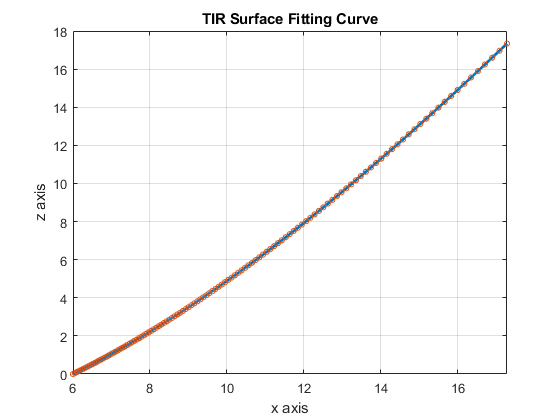


A = figure;
plot(TIR_x,TIR_y,'linewidth',2)
hold on
plot(TIR_s_p(1,:),TIR_s_p(2,:),'o','MarkerSize',4)
xlim([min(TIR_x),max(TIR_x)])
xlabel('x axis')
ylabel('z axis')
grid on
title('TIR Surface Fitting Curve')

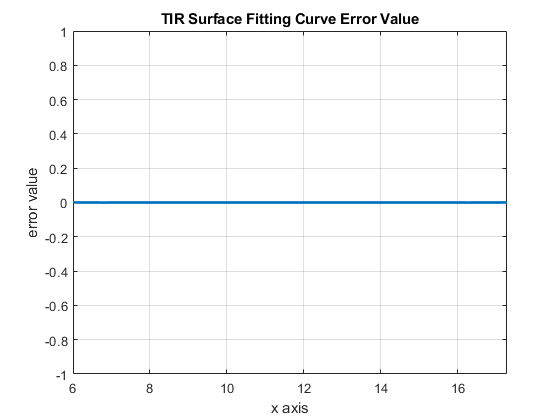



B = figure;
plot(TIR_x,TIR_y-TIR_s_p(2,:),'linewidth',2)
ylim([-1, 1])
xlim([min(TIR_x),max(TIR_x)])
grid on
title('TIR Surface Fitting Curve Error Value')
xlabel('x axis')
ylabel('error value')

### 4-3. Verify Solution

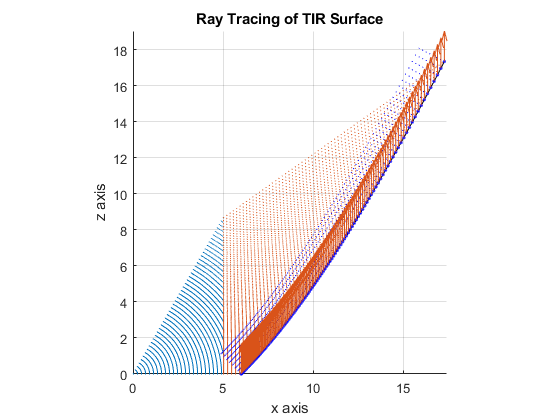

df = polyder(f_TIRsurf);
k = polyval(df,TIR_x);

theta = atand(k);
TIR_grad_x = cosd(theta); TIR_grad_y = sind(theta);

theta_1 = theta+90;
TIR_norm_x = cosd(theta_1); TIR_norm_y = sind(theta_1);

TIR_theta_2 = (180+refraction_angle_top)-2*(180-theta_1+refraction_angle_top);
TIR_t_x = cosd(TIR_theta_2);  TIR_t_y = sind(TIR_theta_2);


C = figure;
line([zeros(1,numel(emission_angle_side));s_i_s_p(1,:)], [zeros(1,numel(emission_angle_side));s_i_s_p(2,:)],'LineStyle',':','linewidth',.5 ...
    ,'color',[0 0.4470 0.7410])
hold on
plot(TIR_x,TIR_y,'color','k')
hold on 
line([s_i_s_p(1,:);TIR_s_p(1,:)],[s_i_s_p(2,:);TIR_s_p(2,:)],'LineStyle',':','color',[0.8500 0.3250 0.0980])
hold on
q = quiver(TIR_x,TIR_y,TIR_norm_x,TIR_norm_y,':','color','b');
q.ShowArrowHead = 'off';
q.Marker = '.';
hold on 
quiver(TIR_x,TIR_y,TIR_t_x,TIR_t_y,'color',[0.8500 0.3250 0.0980]);
axis equal
axis tight
grid on
title('Ray Tracing of TIR Surface')
xlabel('x axis')
ylabel('z axis')

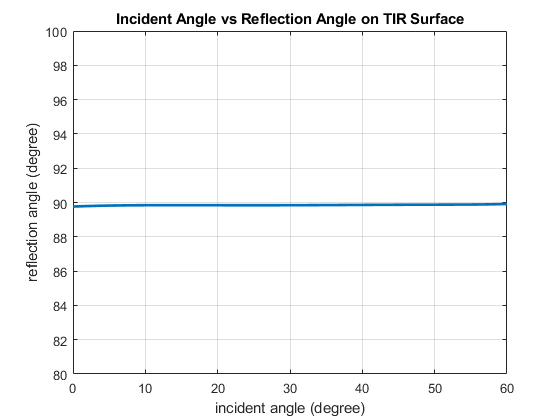


D = figure;
plot(emission_angle_side,TIR_theta_2,'linewidth',2)
xlim([min(emission_angle_side),max(emission_angle_side)])
ylim([80,100])
grid on
xlabel('incident angle (degree)')
ylabel('reflection angle (degree)')
title('Incident Angle vs Reflection Angle on TIR Surface')

## 5. Center Surface Desigin

### 5-1. Center Surface Calculation

slice_num = 201;
R_s_p = zeros(2,slice_num);
R_s_p(1,:) = linspace(s_i_s_p(1,end),0,slice_num);
R_s_p(2,1) = s_i_s_p(2,end);

angle = 90-emission_angle_side(end);
incident_angle = zeros(1,size(R_s_p,2));
incident_angle(1) = angle;
for i = 1:size(R_s_p,2)-1
    unit_angle = atand(sind(angle)/(n_glass-cosd(angle)))-R_angle_correct;
    unit_vector = [cosd(unit_angle),sind(unit_angle)];
    const = (R_s_p(1,i+1)-R_s_p(1,i))/unit_vector(1);
    surf_y = R_s_p(2,i)+const*unit_vector(2);
    surf_x = R_s_p(1,i+1);    R_s_p(2,i+1) = surf_y;
    
    angle = 90-atand(surf_y/surf_x);
    incident_angle(i+1) = angle;
end

### 5-2. Curve Fitting

error_val = 1;
powers = 0;
while error_val > 0.001
    powers = powers+1;
    f_Rsurf = polyfit(R_s_p(1,:),R_s_p(2,:),powers);
    R_x = R_s_p(1,:);
    R_y = polyval(f_Rsurf,R_x);
    error_val = max(R_y-R_s_p(2,:))
end

error_val = 0.1547

error_val = 0.0632

error_val = 0.0047

error_val = 0.0020

error_val = 0.0012

error_val = 2.3510e-04

disp(['Polynomial of Center Curve = ',num2str(f_Rsurf)])

Polynomial of Center Curve = -5.8911e-05  0.00095891  -0.0048018  -0.0059546     0.17405   0.0015179      5.9705


disp(['Polynomial Powers = ',num2str(powers)])

Polynomial Powers = 6


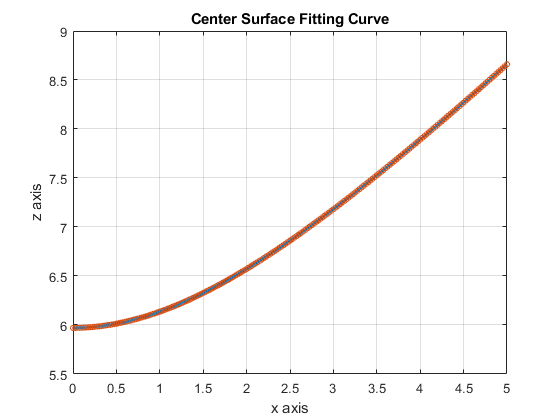


E = figure;
plot(R_x,R_y,'linewidth',2)
hold on
plot(R_s_p(1,:),R_s_p(2,:),'o','MarkerSize',4)
xlim([min(R_x),max(R_x)])
xlabel('x axis')
ylabel('z axis')
grid on
title('Center Surface Fitting Curve')

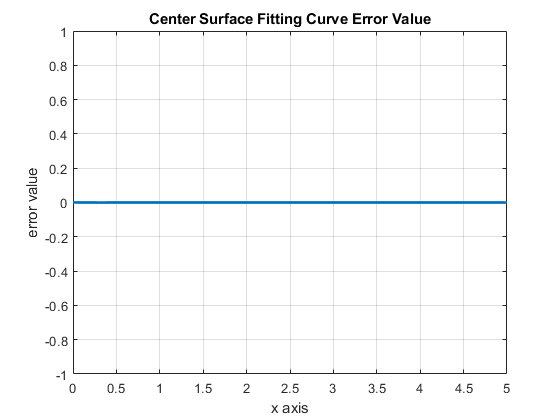


F = figure;
plot(R_x,R_y-R_s_p(2,:),'linewidth',2)
ylim([-1, 1])
xlim([min(R_x),max(R_x)])
grid on
title('Center Surface Fitting Curve Error Value')
xlabel('x axis')
ylabel('error value')

### 5-3. Verify Solution

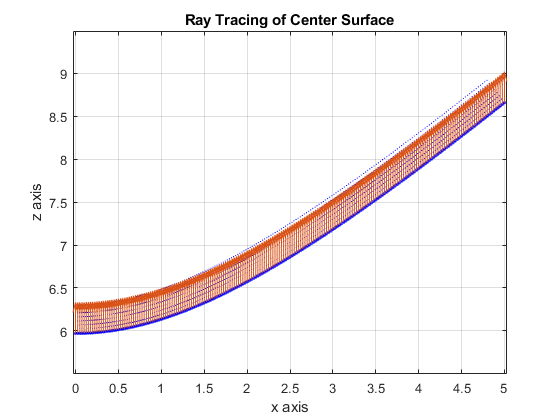

df = polyder(f_Rsurf);
k = polyval(df,R_x);

theta = atand(k);
R_grad_x = cosd(theta); R_grad_y = sind(theta);

theta_1 = theta+90;
R_norm_x = cosd(theta_1); R_norm_y = sind(theta_1);

R_theta_2 = asind(sind(incident_angle+theta)/n_glass)-theta+90;
R_t_x = cosd(R_theta_2);  R_t_y = sind(R_theta_2);

G = figure;
plot(R_x,R_y,'color','k')
hold on
q = quiver(R_x,R_y,R_norm_x,R_norm_y,':','color','b');
q.ShowArrowHead = 'off';
q.Marker = '.';
hold on 
quiver(R_x,R_y,R_t_x,R_t_y,'color',[0.8500 0.3250 0.0980]);
axis equal
grid on
title('Ray Tracing of Center Surface')
xlabel('x axis')
ylabel('z axis')

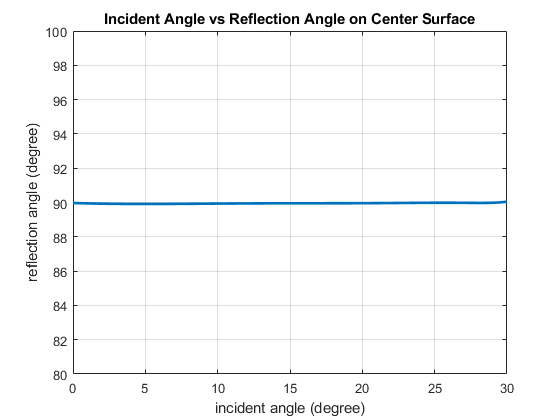


H = figure;
plot(incident_angle,R_theta_2,'linewidth',2)
ylim([80,100])
grid on
xlabel('incident angle (degree)')
ylabel('reflection angle (degree)')
title('Incident Angle vs Reflection Angle on Center Surface')

## 6. TIR Lens Ray Tracing

### 6-1. Ray Tracing

Propagate_distance = 10;


Data.TIR_ang = TIR_theta_2;
Data.R_ang = R_theta_2;
Data.area1_x = [zeros(1,numel(emission_angle_side)),zeros(1,slice_num);s_i_s_p(1,:),R_s_p(1,:)];
Data.area1_y = [zeros(1,numel(emission_angle_side)),zeros(1,slice_num);s_i_s_p(2,:),R_s_p(2,:)];
Data.area2_1_x = [s_i_s_p(1,:);TIR_s_p(1,:)];
Data.area2_1_y = [s_i_s_p(2,:);TIR_s_p(2,:)];

exit_hight = ceil(TIR_y(end));
% TIR Part
const = (exit_hight-TIR_s_p(2,:))./sind(Data.TIR_ang);
TIR_ref_to_exit_x = TIR_s_p(1,:)+cosd(Data.TIR_ang).*const;
TIR_ref_to_exit_y = ones(1,size(TIR_ref_to_exit_x,2))*exit_hight;

% Center Part
const = (exit_hight-R_s_p(2,:))./sind(Data.R_ang);
R_to_exit_x = R_s_p(1,:)+cosd(Data.R_ang).*const;
R_to_exit_y = ones(1,size(R_to_exit_x,2))*exit_hight;

Data.area2_2_x = [TIR_s_p(1,:),R_s_p(1,:);TIR_ref_to_exit_x,R_to_exit_x];
Data.area2_2_y = [TIR_s_p(2,:),R_s_p(2,:);TIR_ref_to_exit_y,R_to_exit_y];


% TIR Part
TIR_exit_angle = asind(sind(90-Data.TIR_ang)*n_glass)-90;
const = (Propagate_distance+exit_hight)-TIR_ref_to_exit_y./sind(TIR_exit_angle);
TIR_exit_to_distance_x = TIR_ref_to_exit_x+cosd(TIR_exit_angle).*const;
TIR_exit_to_distance_y = ones(1,size(TIR_exit_to_distance_x,2))*(Propagate_distance+exit_hight);

% Center Part
R_exit_angle = asind(sind(90-Data.R_ang)*n_glass)-90;
const = (Propagate_distance+exit_hight)-R_to_exit_y./sind(R_exit_angle);
R_exit_to_distance_x = R_to_exit_x+cosd(R_exit_angle).*const;
R_exit_to_distance_y = ones(1,size(R_exit_to_distance_x,2))*(Propagate_distance+exit_hight);

Data.area3_x = [TIR_ref_to_exit_x,R_to_exit_x;TIR_exit_to_distance_x,R_exit_to_distance_x];
Data.area3_y = [TIR_ref_to_exit_y,R_to_exit_y;TIR_exit_to_distance_y,R_exit_to_distance_y];

I = figure;
line(Data.area1_x,Data.area1_y,'linestyle','-','color','#00314F')
hold on
line(Data.area2_1_x,Data.area2_1_y,'linestyle','-','color','#3E6B7E')
hold on
line(Data.area2_2_x,Data.area2_2_y,'linestyle',':','linewidth',.1,'color','#3E6B7E')
hold on
line(Data.area3_x,Data.area3_y,'linewidth',.1,'color','#FCE4A8')
hold on
plot(R_x,R_y,'color','k','linewidth',2)   % Refract Surface
hold on
plot(TIR_x,TIR_y,'color','k','linewidth',2)   % TIR Surface
hold on
line([R_x(1),R_x(1)],[0,R_y(1)],'color','k','linewidth',2)    % Side Incident Surface
hold on
line([0,TIR_x(end)],[exit_hight,exit_hight],'color','k','linewidth',2)    % Exit pupil 
hold on
line([R_x(1),TIR_x(1)],[0,0],'color','k','linewidth',2)   % Side Surface to TIR Surface Distance
hold on

line(-Data.area1_x,Data.area1_y,'linestyle','-','color','#00314F')
hold on
line(-Data.area2_1_x,Data.area2_1_y,'linestyle','-','color','#3E6B7E')
hold on
line(-Data.area2_2_x,Data.area2_2_y,'linestyle',':','linewidth',.1,'color','#3E6B7E')
hold on
line(-Data.area3_x,Data.area3_y,'linewidth',.1,'color','#FCE4A8')
hold on
plot(-R_x,R_y,'color','k','linewidth',2)   % Refract Surface
hold on
plot(-TIR_x,TIR_y,'color','k','linewidth',2)   % TIR Surface
hold on
line(-[R_x(1),R_x(1)],[0,R_y(1)],'color','k','linewidth',2)    % Side Incident Surface
hold on
line(-[0,TIR_x(end)],[exit_hight,exit_hight],'color','k','linewidth',2)    % Exit pupil 
hold on
line(-[R_x(1),TIR_x(1)],[0,0],'color','k','linewidth',2)   % Side Surface to TIR Surface Distance
grid on
grid minor
axis equal
title('TIR Lens Ray Tracing')
xlabel('x axis')
ylabel('z axis')

### 6-2. Surface Cut at Propagate Distance

x = Data.area3_x(2,:);
y = zeros(1,numel(x));
rotate_degree = linspace(0,2*pi,999);
x_rotate = zeros(numel(rotate_degree),numel(x));
y_rotate = zeros(numel(rotate_degree),numel(x));
for i = 1:numel(rotate_degree)
    x_rotate(i,:) = cos(rotate_degree(i))*x-sin(rotate_degree(i))*y;
    y_rotate(i,:) = sin(rotate_degree(i))*x+cos(rotate_degree(i))*y;
end

J = figure;
plot(x_rotate,y_rotate,'-','color','#00314F')
axis equal
grid on
xlabel('x axis')
ylabel('y axis')
title(['Surface Cut at Porpagated ',num2str(Propagate_distance),' Unit Distance'])


## Save Figure

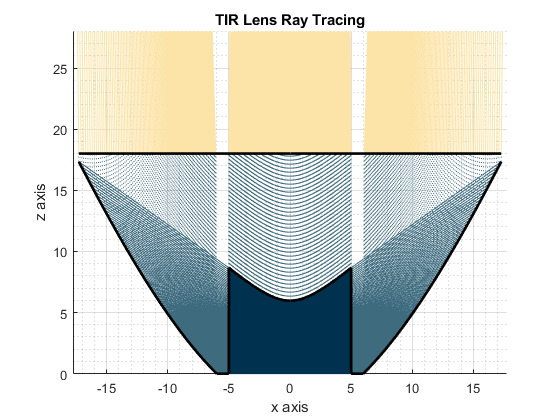

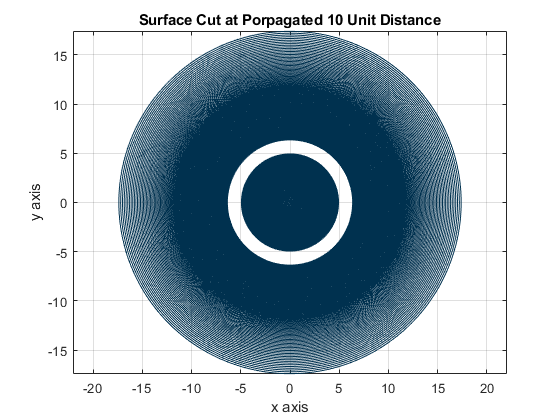

save_figure = 1;
if save_figure == 1
    saveas(A,'TIR Surface Fitting Curve.png')
    saveas(B,'TIR Surface Fitting Curve Error Value.png')
    saveas(C,'Ray Tracing of TIR Surface.png')
    saveas(D,'Incident Angle vs Reflection Angle on TIR Surface.png')
    saveas(E,'Center Surface Fitting Curve.png')
    saveas(F,'Center Surface Fitting Curve Error Value.png')
    saveas(G,'Ray Tracing of Center Surface.png')
    saveas(H,'Incident Angle vs Reflection Angle on Center Surface.png')
    saveas(I,'TIR Lens Ray Tracing.png')
    saveas(J,['Surface Cut at Porpagated ',num2str(Propagate_distance),' Unit Distance.png'])
end